# Анализ линейной стационарной дискретной системы

Сформируем входное воздействие - ЛЧМ сигнал:

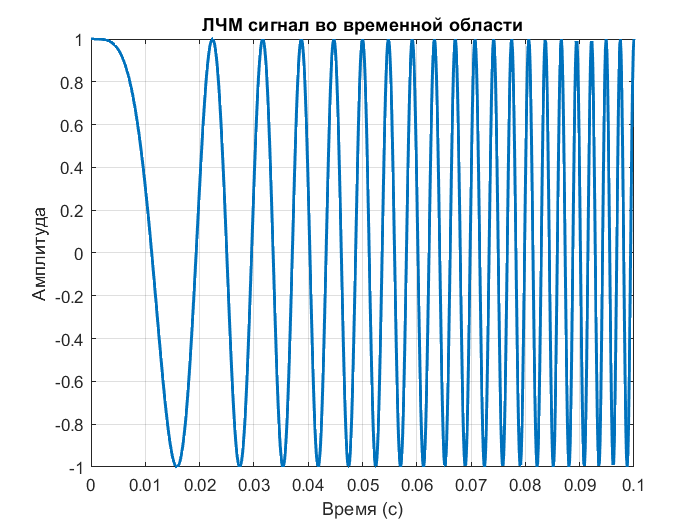

fs = 8e3;
dt = 1/fs;
t = 0:dt:1;
x = chirp(t, 0, 1, 4000);
plot(t, x, 'LineWidth', 2);
xlim([0 0.1]);
grid on;
title('ЛЧМ сигнал во временной области');
xlabel('Время (с)');
ylabel('Амплитуда');

Определим коэффиценты фильтра, отобразим его АЧХ и ФЧХ при помощи встроенной функции **freqz**, вычислим нули и полюса передаточной функции и отобразим их на диаграмме:

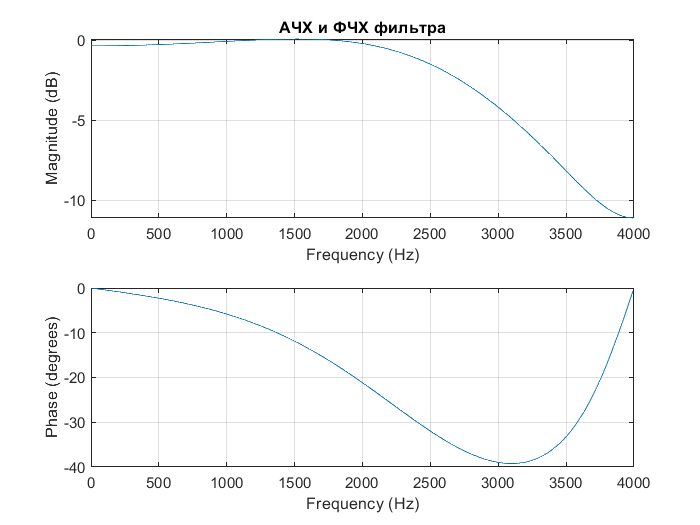

b = [0.75 0.5];
a = [1 0.2 0.1];
freqz(b, a, [], fs);
title('АЧХ и ФЧХ фильтра');

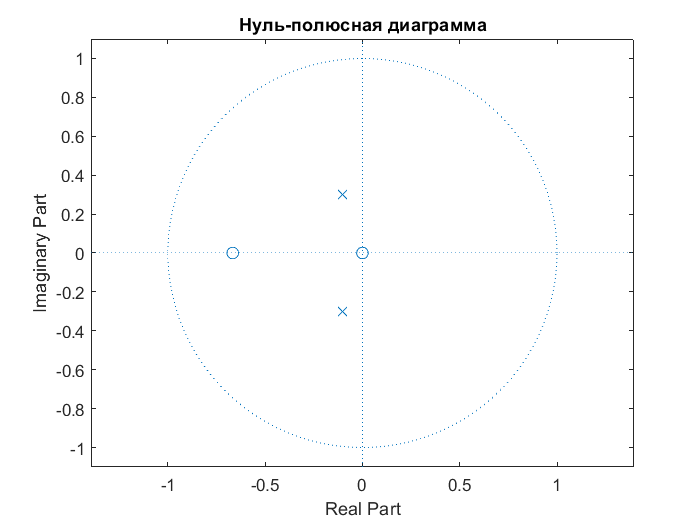

[z, p, k] = tf2zpk(b, a);
zplane(z, p);
title('Нуль-полюсная диаграмма');

Воспользуемся функцией помошником для отображения передаточной функции на комплексной плоскости. Убедимся, что форма АЧХ соответствует определённой ранее:

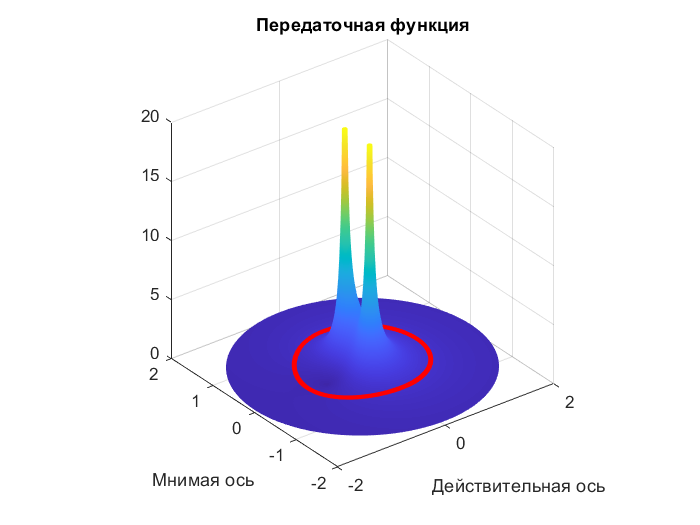

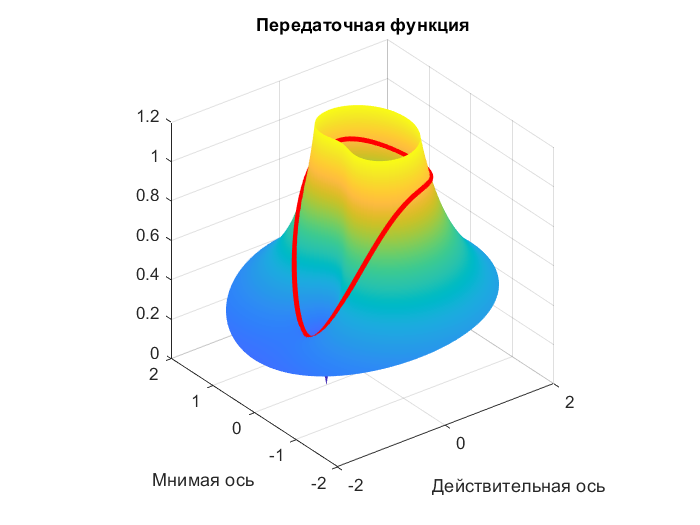

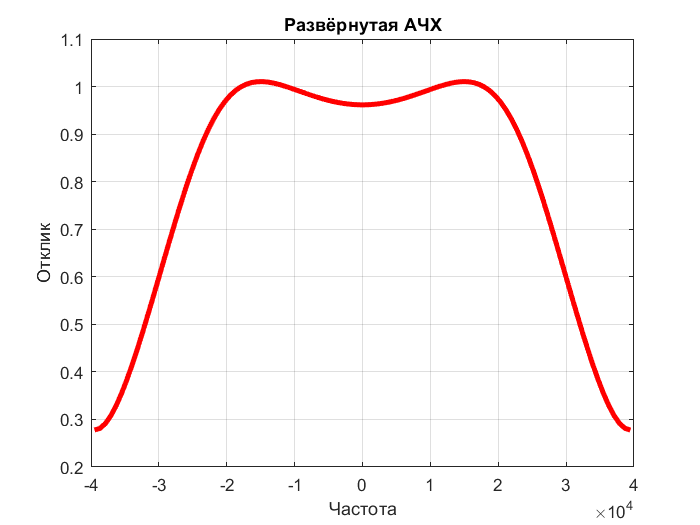

helperfunc2(b, a, fs);

Пропустим входной сигнал через фильтр - воспользуемся функцией **filter**. Отобразим во временной области входной и выходной сигналы:

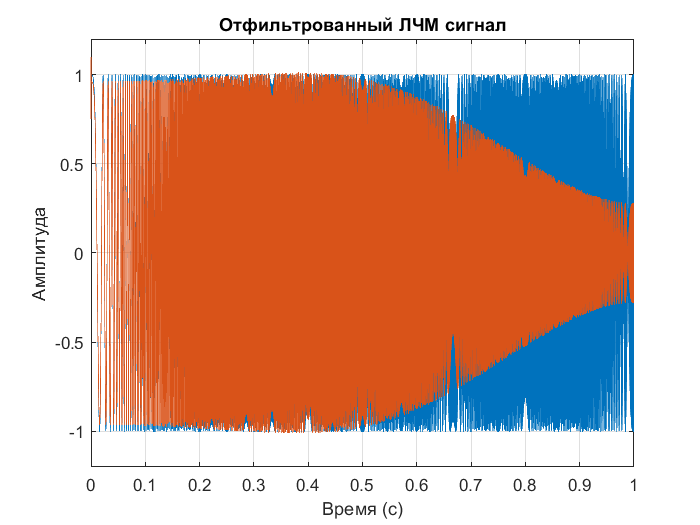

y = filter(b, a, x);
plot(t, x);
ylim([-1.2 1.2]);
hold on;
plot(t, y);
title('Отфильтрованный ЛЧМ сигнал');
xlabel('Время (с)');
ylabel('Амплитуда');
grid on;
hold off;

Вычислим импульсную характеристику фильтра. Попробуем посчитать выход через операцию дискретной свёртки и сравним с откликом, вычисленным ранее:

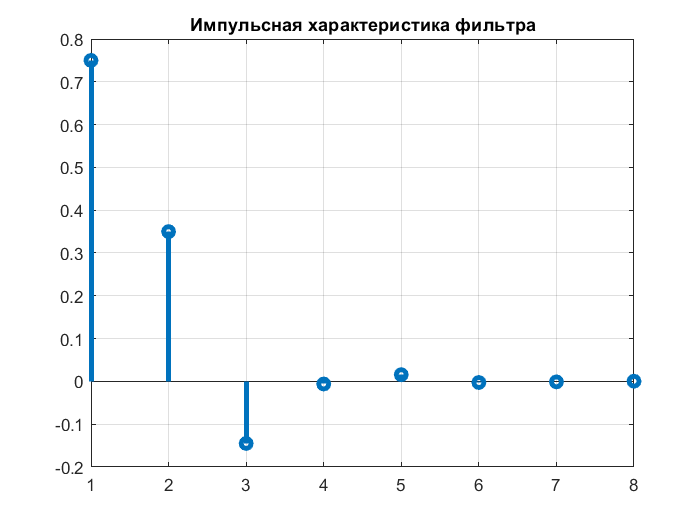

h = impz(b, a);
stem(h, 'LineWidth', 3);
title('Импульсная характеристика фильтра');
grid on;

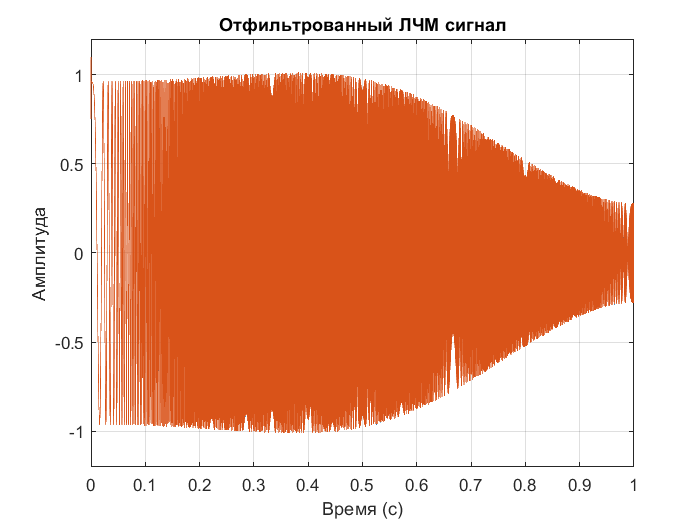

y2 = conv(x, h);
plot(t, y);
ylim([-1.2 1.2]);
hold on;
plot(t, y2(1:8001));
title('Отфильтрованный ЛЧМ сигнал');
xlabel('Время (с)');
ylabel('Амплитуда');
grid on;
hold off;